clear; clc;

seed_varieties = ["zd", "jd", "nh", "jh"];   %% " "
file_names = [25, 50, 75, 100, 125, 150];    %%

for index1 = 1:length(seed_varieties)
    
    seed_variety = seed_varieties(index1);
    
    for index2 = 1:length(file_names)
        
        file_name = file_names(index2);
        
        tic
        data_Pre = pretreatment_nir(seed_variety, file_name);
        toc
        
        mat_name = char(strcat(seed_variety, '_', num2str(file_name), '_nir_Pre'));
        mat_path = char(strcat('D:\files\spectral_analysis\mat_demo\demo_pretreatment\nir_data\', ...
                               seed_variety, '_', num2str(file_name), '_nir_Pre'));
        
        save(mat_path, 'data_Pre');  
       % eval([mat_name, '= data_Pre;'])   % just name it in filefold now now now!
        fprintf(strcat(mat_name,' has been done!'))
        
    end  
     
end

历时 117.714274 秒。


zd_25_nir_Pre has been done!

历时 115.104648 秒。


zd_50_nir_Pre has been done!

历时 116.207490 秒。


zd_75_nir_Pre has been done!

历时 114.688541 秒。


zd_100_nir_Pre has been done!

历时 114.059353 秒。


zd_125_nir_Pre has been done!

历时 117.600000 秒。


zd_150_nir_Pre has been done!

历时 115.345230 秒。


jd_25_nir_Pre has been done!

历时 112.996181 秒。


jd_50_nir_Pre has been done!

历时 108.687396 秒。


jd_75_nir_Pre has been done!

历时 109.678945 秒。


jd_100_nir_Pre has been done!

历时 108.785520 秒。


jd_125_nir_Pre has been done!

历时 113.451250 秒。


jd_150_nir_Pre has been done!

历时 108.898469 秒。


nh_25_nir_Pre has been done!

历时 108.912229 秒。


nh_50_nir_Pre has been done!

历时 112.633283 秒。


nh_75_nir_Pre has been done!

历时 112.012422 秒。


nh_100_nir_Pre has been done!

历时 111.708357 秒。


nh_125_nir_Pre has been done!

历时 114.317425 秒。


nh_150_nir_Pre has been done!

历时 116.622203 秒。


jh_25_nir_Pre has been done!

历时 114.981392 秒。


jh_50_nir_Pre has been done!

历时 114.486579 秒。


jh_75_nir_Pre has been done!

历时 112.957137 秒。


jh_100_nir_Pre has been done!

历时 110.134450 秒。


jh_125_nir_Pre has been done!

历时 108.019573 秒。


jh_150_nir_Pre has been done!

path = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\nir_data";
mats = dir(fullfile(path, '*.mat'));

for i = 1:length(mats)
    mat_name = mats(i).name(1:end-4);
    eval([mat_name, ' = load(fullfile(path, mats(i).name)).data_Pre;'])
end

## combine

X_nir = []; 
y_nir = [];

seed_varieties = ["zd", "jd", "nh", "jh"]; 
file_names = [25, 50, 75, 100, 125, 150];

for index1 = 1:length(seed_varieties)    
    seed_variety = seed_varieties(index1);    
    for index2 = 1:length(file_names)        
        file_name = file_names(index2);
        
        mat_name = char(strcat(seed_variety, '_', num2str(file_name), '_nir_Pre'));
        data = eval([mat_name, '.avedata;']);
        X_nir = [X_nir; data];
        y_incre = ones(25, 1) * index1;
        y_nir = [y_nir; y_incre];
    end
end

effwavelengths = zd_25_nir_Pre.effwavelengths;

X_nir_air = pre_airpls(X_nir, 10e3)

X_nir_air =        62.813       61.081       61.284       36.534        26.26       34.168       20.528       8.5736       9.9178       2.1842       7.0432       1.0009      -1.4983       2.2402       2.6291      -9.2781       -3.791      -4.9628      -2.9136      -8.7828      0.32554      -1.5843      -3.5194       2.2658      -1.2773        2.069     -0.88674      -3.4907      -5.4753      0.51158      -2.3189      -1.1584      -2.3892      -2.3267      -3.4236      -2.8645      0.89901      -2.1095     -0.99308      -7.1615     -0.94809     -0.15653       2.8214       4.8908       1.7111        3.341       5.8723       3.4891       5.3998         4.52
        73.58       61.748        60.69       44.722        33.84       32.157        27.74       13.196       12.418        4.488       3.2066       2.2104       1.4661       1.4551        1.277      -7.1629      -5.3882      -5.8769      -3.8623       -7.855      -1.1199     -0.41165      -2.4562       2.5645      -2.7014      -1.016


X_nir_air_sg = pre_sgfilter(X_nir_air, 15, 2, 0);

X_nir_air_sg_v = reshape(X_nir_air_sg, 1, size(X_nir_air_sg, 1)*size(X_nir_air_sg, 2));
X_nir_air_sg_01_v = mapminmax(X_nir_air_sg_v, 0, 1);
X_nir_air_sg_01 = reshape(X_nir_air_sg_01_v, size(X_nir_air_sg, 1), size(X_nir_air_sg, 2));
% X_nir_air_sg_snv = pre_snv(X_nir_air_sg);

X_nir_norm = X_nir_air_sg_01

X_nir_norm =       0.29611      0.26984      0.24574      0.22383      0.20409      0.18654      0.17117      0.15797       0.1468      0.13718      0.13307      0.12661      0.12126      0.11869      0.11706      0.11483      0.11314      0.11189      0.11237      0.11345      0.11478      0.11761      0.11985      0.11993       0.1205      0.12075       0.1211      0.11937      0.11912      0.11771      0.11657      0.11678      0.11763      0.11781       0.1178      0.11694      0.11553      0.11702      0.11798      0.11928      0.12144       0.1234      0.12542      0.12693      0.12992      0.13227      0.13529      0.13562      0.13578       0.1356
      0.31053      0.28326      0.25814      0.23517      0.21435      0.19568      0.17916      0.16479      0.15349      0.14241      0.13547      0.12834      0.12256      0.11783      0.11589      0.11373       0.1124      0.11219       0.1121      0.11368      0.11431      0.11542      0.11755       0.1177      0.11852      0.120

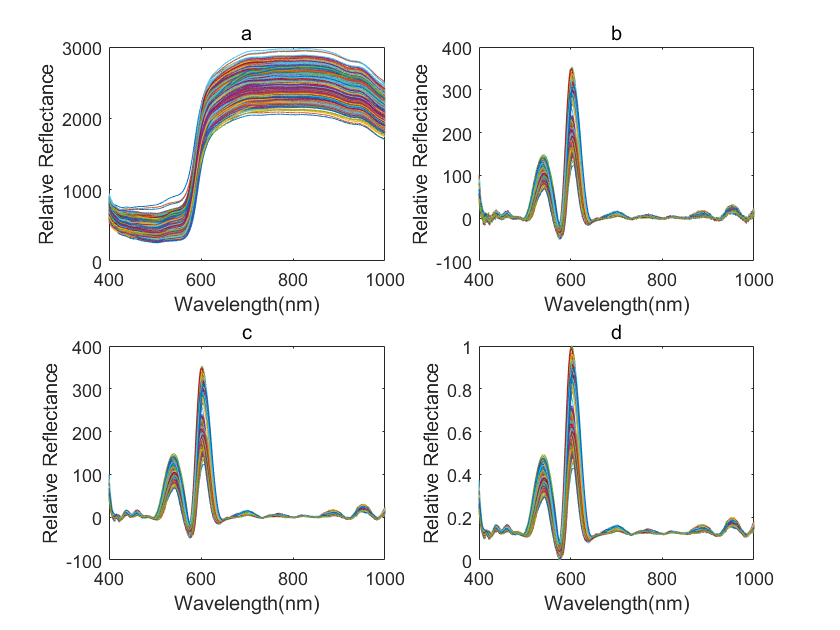

figure;
subplot(2,2,1);
for k = 1:size(X_nir, 1)
    plot(effwavelengths, X_nir(k, :));
    hold on;
end 
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('a')

subplot(2,2,2);
for k = 1:size(X_nir, 1)
    plot(effwavelengths, X_nir_air(k, :));
    hold on;
end 
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('b')

subplot(2,2,3);
for k = 1:size(X_nir, 1)
    plot(effwavelengths, X_nir_air_sg(k, :));
    hold on;
end
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('c')

subplot(2,2,4);
for k = 1:size(X_nir, 1)
    plot(effwavelengths, X_nir_air_sg_01(k, :));
    hold on;
end 
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('d')

% figure('Units','normalized','Position',[0, 0, 0.75, 1]);
% for k = 1:size(X_nir, 1)
%     plot(effwavelengths, X_nir(k, :), "LineWidth", 1);
%     hold on;
% end 
% xlim([400, 1000])
% xlabel('Wavelength(nm)')
% ylabel('Relative Reflectance')
% set(gca,'fontsize',30, 'FontWeight','bold');
% title("original NIR data")
% 
% figure('Units','normalized','Position',[0, 0, 0.75, 1]);
% for k = 1:size(X_nir, 1)
%     plot(effwavelengths, X_nir_sg1_snv(k, :), "LineWidth", 1);
%     hold on;
% end 
% xlim([400, 1000])
% xlabel('Wavelength(nm)')
% ylabel('Relative Reflectance')
% set(gca,'fontsize',30, 'FontWeight','bold');
% title('air & sg & norm NIR data')

y1 = find(y_nir == 1); 
y2 = find(y_nir == 2);
y3 = find(y_nir == 3);
y4 = find(y_nir == 4);

data = X_nir_air_sg_01;
avedata_variety_nir = zeros(4, length(effwavelengths));

avedata_variety_nir(1, :) = mean(data(y1(1:50), :), 1);
avedata_variety_nir(2, :) = mean(data(y2(1:50), :), 1);
avedata_variety_nir(3, :) = mean(data(y3(1:50), :), 1);
avedata_variety_nir(4, :) = mean(data(y4(1:50), :), 1);


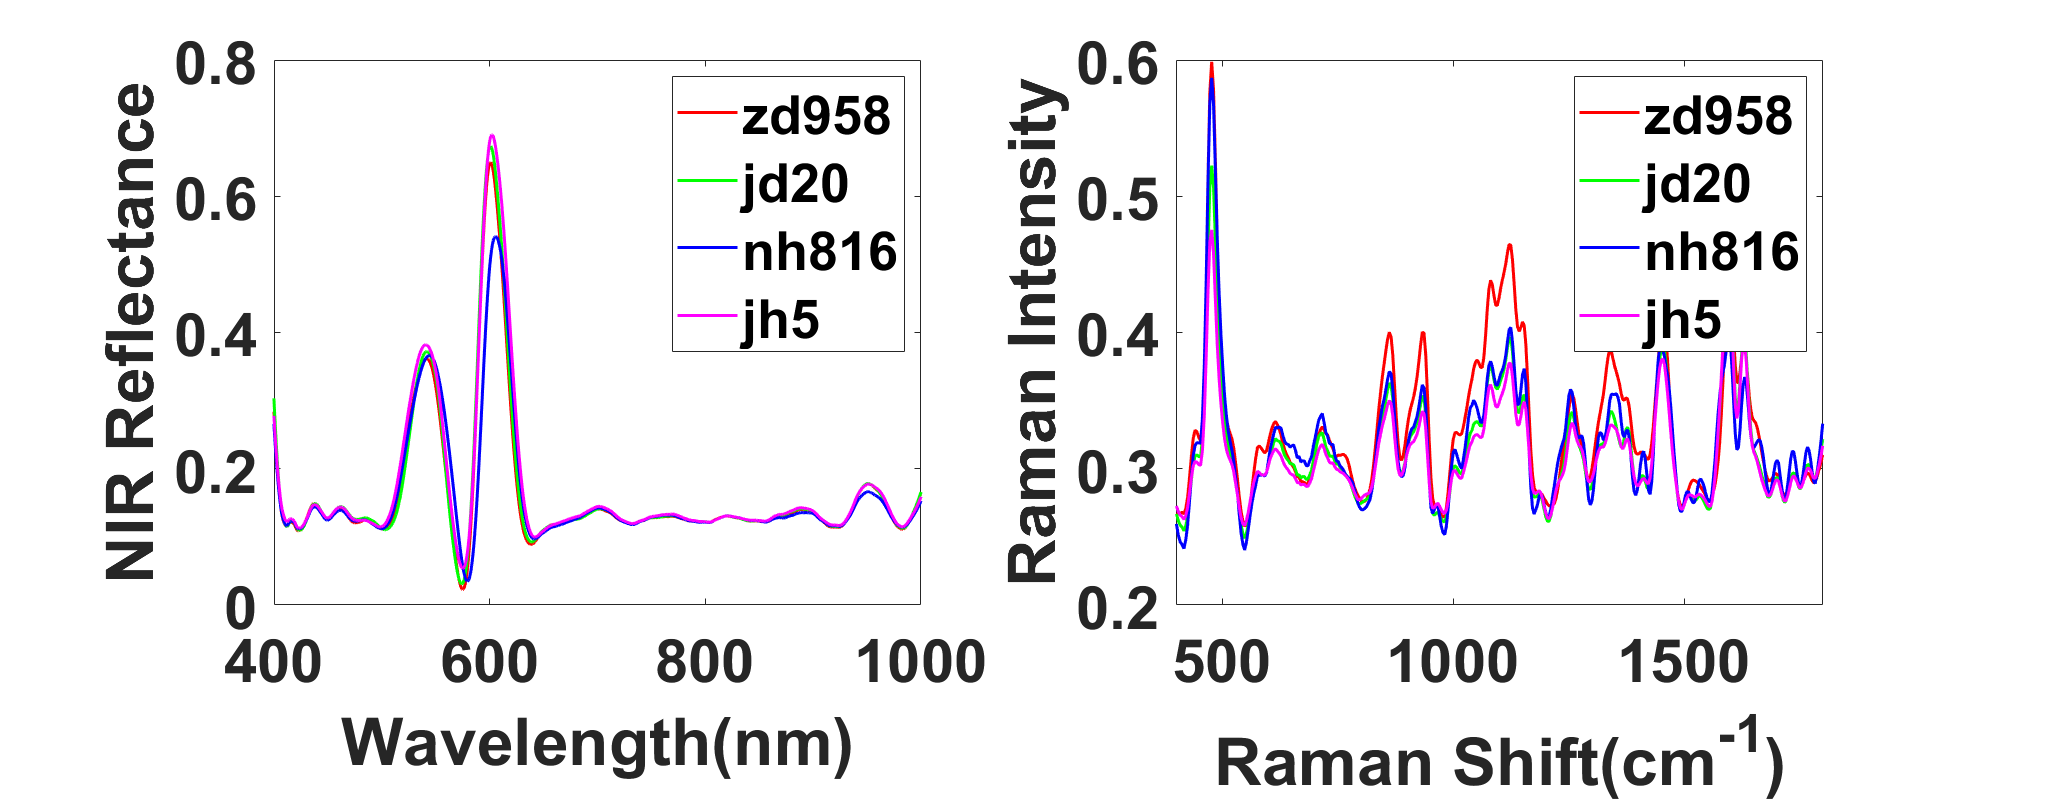

figure('Units','normalized','Position',[0, 0, 0.8, 0.5]);

subplot(1,2,1);
seed_varieties = ["zd958", "jd20", "nh816", "jh5"];
colors = ['r', 'g', 'b', 'm'];
for k = 1:length(seed_varieties)
    plot(effwavelengths, avedata_variety_nir(k, :), "Color", colors(k), "LineWidth", 1.5);
    hold on;
end

% for k = 1:length(seed_varieties)
%     plot(raman_wavelengths, avedata_variety(k, :), "Color", colors(k), "LineWidth", 1.5);
%     hold on;
% end

xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('NIR Reflectance')
legend(seed_varieties) 
set(gca,'fontsize',30, 'FontWeight','bold');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1,2,2);

seed_varieties = ["zd958", "jd20", "nh816", "jh5"];
colors = ['r', 'g', 'b', 'm'];

for k = 1:length(seed_varieties)
    plot(effshift, avedata_variety(k, :), "Color", colors(k), "LineWidth", 1.5);
    hold on;
end

xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
legend(seed_varieties) 
set(gca,'fontsize',30, 'FontWeight','bold');